# **Deriving Equations of Motion of Double Pendulum **

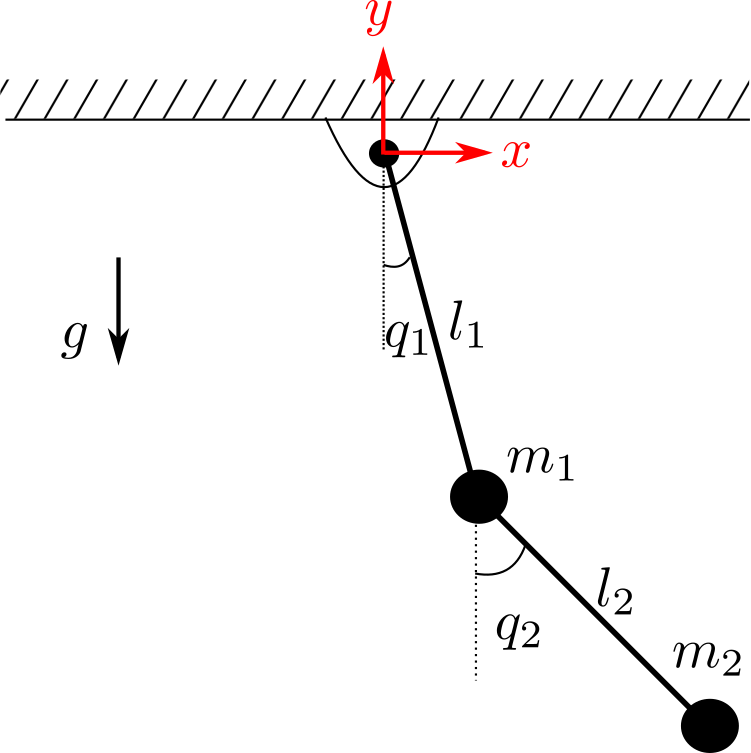

Derive the equations of motion of this system which is in the form of:


$$M(q) \ddot q + C(q, \dot q) \dot q + G(q) = 0$$
 

What are the formulas for matrices $M(q), C(q, \dot q)$ and $G(q)$? 

syms m1 m2 l1 l2 g 
syms q1 q2 dq1 dq2 ddq1 ddq2

# Kinematics**: **

**Position and velocity of m1:**

disp('-------------------------')

-------------------------


disp('Position and velocity of m1:')

Position and velocity of m1:


x1 = l1 * sin(q1)

$$x1 = l_{1}\,\sin\left(q_{1}\right)$$

y1 = -l1 * cos(q1)

$$y1 = -l_{1}\,\cos\left(q_{1}\right)$$

dx1 = diff(x1, q1) * dq1

$$dx1 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)$$

dy1 = diff(y1, q1) * dq1

$$dy1 = {\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)$$

dx1

$$dx1 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)$$

**Position and velocity of m2:**

disp('-------------------------')

-------------------------


disp('Position and velocity of m2:')

Position and velocity of m2:


x2 = l1 * sin(q1) + l2 * sin(q2)

$$x2 = l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\sin\left(q_{2}\right)$$

y2 = -l1 * cos(q1) - l2 * cos(q2)  

$$y2 = -l_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)$$

dx2 = diff(x2, q1) * dq1 + diff(x2, q2) * dq2

$$dx2 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)$$

dy2 = diff(y2, q1) * dq1 + diff(y2, q2) * dq2

$$dy2 = {\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)$$

# Dynamics:

**Kinetic and potential energies of m1:**

disp('-------------------------')

-------------------------


disp('Kinetic and potential energies of m1:')

Kinetic and potential energies of m1:


T1 = 0.5*m1*(dx1^2 + dy1^2)

$$T1 = \frac{m_{1}\,\left({{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}+{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}\right)}{2}$$

V1 = m1*g*y1 

$$V1 = -g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

T1 = simplify(T1) % To simplify the symbolic equations

$$T1 = \frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{2}$$

V1 = simplify(V1)

$$V1 = -g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

**Kinetic and potential energies of m2:**

disp('-------------------------')

-------------------------


disp('Kinetic and potential energies of m2:')

Kinetic and potential energies of m2:


T2 = 0.5*m2*(dx2^2 +dy2^2)

$$T2 = \frac{m_{2}\,\left({\left({\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{\left({\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)\right)}^{2}\right)}{2}$$

V2 = m2*g*y2 

$$V2 = -g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\right)$$

T2 = simplify(T2, 'Steps', 50) % To simplify the symbolic equations

$$T2 = \frac{m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}+2\,\cos\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\right)}{2}$$

V2 = simplify(V2, 'Steps', 50)

$$V2 = -g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\right)$$

% T2 = simplify(T2, 'Steps', 50) % sometimes you need to 'increase' the simplification level
% V2 = simplify(V2)

## Recall Lagrangian:


$$L(q, \dot q) = T(q, \dot q) - V(q)$$


## Lagrange equations of motion:

$\frac{d}{dt}(\frac{\partial L}{\partial \dot q_i }) - \frac{\partial L}{\partial q_i} = 0$           for i = 1, 2�

disp('-------------------------')

-------------------------


disp('Cacluate the Lagrangian of the system: ')

Cacluate the Lagrangian of the system: 


T = T1 + T2 % this is the total kinetic energy of the system 

$$T = \frac{m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}+2\,\cos\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\right)}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{2}$$

T = simplify(T, 'Steps',50)

$$T = \frac{m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}+2\,\cos\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\right)}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{2}$$

V = V1 + V2 % this is the total kinetic energy of the system

$$V = -g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\right)-g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

V = simplify(V, 'Steps',50)

$$V = -g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\right)-g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

L = T-V% this is the lagrangian of the system 

$$L = \frac{m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}+2\,\cos\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\right)}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{2}+g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

L = simplify(L, 'Steps', 50)

$$L = \frac{m_{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}+2\,\cos\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}+{{\mathrm{dq}}_{2}}^{2}\,{l_{2}}^{2}\right)}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{1}}{2}+g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{2}\right)\right)+g\,l_{1}\,m_{1}\,\cos\left(q_{1}\right)$$

We use $dLddq$ as short for $\frac{\partial L}{\partial \dot q}$ and $dLdq$ for $\frac{\partial L}{\partial q}$.     

disp('-------------------------')

-------------------------


disp('Calculate the partial derivatives of Lagrangian:')

Calculate the partial derivatives of Lagrangian:


dLddq1 = diff(L, dq1);
dLddq2 = diff(L, dq2)% partial derivative of L wrt dq2

$$dLddq2 = \frac{m_{2}\,\left(2\,{\mathrm{dq}}_{2}\,{l_{2}}^{2}+2\,{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\,l_{2}\right)}{2}$$

dLdq1 = diff(L, q1)% partial derivative of L wrt q1

$$dLdq1 = -g\,l_{1}\,m_{1}\,\sin\left(q_{1}\right)-g\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)$$

dLdq2 = diff(L, q2)% partial derivative of L wrt q2

$$dLdq2 = {\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)-g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right)$$

dLddq1 = simplify(dLddq1)

$$dLddq1 = \frac{m_{2}\,\left(2\,{\mathrm{dq}}_{1}\,{l_{1}}^{2}+2\,{\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{1}-q_{2}\right)\,l_{1}\right)}{2}+{\mathrm{dq}}_{1}\,{l_{1}}^{2}\,m_{1}$$

dLddq2 = simplify(dLddq2)

$$dLddq2 = l_{2}\,m_{2}\,\left({\mathrm{dq}}_{2}\,l_{2}+{\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)$$

dLdq1 = simplify(dLdq1)

$$dLdq1 = -l_{1}\,\left(g\,m_{1}\,\sin\left(q_{1}\right)+g\,m_{2}\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\right)$$

dLdq2 = simplify(dLdq2)

$$dLdq2 = -l_{2}\,m_{2}\,\left(g\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\right)$$

We use dLddq_dt for $\frac{d}{dt}(\frac{\partial L}{\partial \dot q})$

This is to calculate the formula for $\frac{d}{dt}(\frac{\partial L}{\partial \dot q_1})$:


disp('-------------------------')

-------------------------


dLddq1_dt = diff(dLddq1, q1) * dq1 + diff(dLddq1, q2) * dq2 + diff(dLddq1, dq1) * ddq1 + diff(dLddq1, dq2) * ddq2

$$dLddq1\_dt = l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{2}}^{2}-{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{2}+{\mathrm{ddq}}_{1}\,\left({l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}\right)+{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)$$

This is to calculate the formula for $\frac{d}{dt}(\frac{\partial L}{\partial \dot q_2})$:

dLddq2_dt = diff(dLddq2, q1) * dq1 + diff(dLddq2, q2) * dq2 + diff(dLddq2, dq1) * ddq1 + diff(dLddq2, dq2) * ddq2

$$dLddq2\_dt = -l_{1}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}\,l_{2}+{\mathrm{dq}}_{2}\,l_{1}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{\mathrm{dq}}_{1}\,l_{2}+{\mathrm{ddq}}_{2}\,m_{2}\,{l_{2}}^{2}+{\mathrm{ddq}}_{1}\,l_{1}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\,l_{2}$$

disp('-------------------------')

-------------------------


disp('Calculate equations of motion: ')

Calculate equations of motion: 


Eq1 = dLddq1_dt - dLdq1 % recall Lagrange equations

$$Eq1 = {\mathrm{ddq}}_{1}\,\left({l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}\right)+l_{1}\,\left(g\,m_{1}\,\sin\left(q_{1}\right)+g\,m_{2}\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\right)+{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)+{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)$$

Eq2 = dLddq2_dt - dLdq2 % recall Lagrange equations

$$Eq2 = l_{2}\,m_{2}\,\left(g\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,\sin\left(q_{1}-q_{2}\right)\right)+{\mathrm{ddq}}_{2}\,{l_{2}}^{2}\,m_{2}+{\mathrm{ddq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)-{{\mathrm{dq}}_{1}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)+{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)$$

Eq1 = simplify(Eq1, 'Steps', 50)% simplify Eq1 in 50 steps

$$Eq1 = l_{1}\,\left(l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{2}}^{2}+g\,m_{1}\,\sin\left(q_{1}\right)+g\,m_{2}\,\sin\left(q_{1}\right)+{\mathrm{ddq}}_{1}\,l_{1}\,m_{1}+{\mathrm{ddq}}_{1}\,l_{1}\,m_{2}+{\mathrm{ddq}}_{2}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\right)$$

Eq2 = simplify(Eq2, 'Steps', 50)% Eq2 in 50 steps

$$Eq2 = l_{2}\,m_{2}\,\left(-l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,l_{2}+g\,\sin\left(q_{2}\right)+{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right)$$


disp('-------------------------')

-------------------------


disp('Calculate Mass matrix (M), Corriolis and gravity terms (C and  G):')

Calculate Mass matrix (M), Corriolis and gravity terms (C and  G):


Eq = simplify(collect([Eq1; Eq2], [ddq1, ddq2, dq1, dq2])) 

$$Eq = \left(\begin{array}{c} \left(l_{1}\,\left(l_{1}\,m_{1}+l_{1}\,m_{2}\right)\right)\,{\mathrm{ddq}}_{1}+\left(l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\right)\,{\mathrm{ddq}}_{2}+\left(l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\right)\,{{\mathrm{dq}}_{2}}^{2}+l_{1}\,\left(g\,m_{1}\,\sin\left(q_{1}\right)+g\,m_{2}\,\sin\left(q_{1}\right)\right)\\ l_{2}\,m_{2}\,\left(-l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,l_{2}+g\,\sin\left(q_{2}\right)+{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right) \end{array}\right)$$

G(1, 1) = m1*g*l1*sin(q1)+m2*g*l1*sin(q1) % hint: you can use subs function 

$$G = \left(\begin{array}{c} g\,l_{1}\,m_{1}\,\sin\left(q_{1}\right)+g\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)\\ g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

G(2, 1) = m2*g*l2*sin(q2)

$$G = \left(\begin{array}{c} g\,l_{1}\,m_{1}\,\sin\left(q_{1}\right)+g\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)\\ g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

M(1, 1) = m1*l1^2 + m2*l1^2 % hint: you can use subs function; don't forget to subtract the G term

$$M = \left(\begin{array}{cc} {l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2} & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$

M(1, 2) = m2*l1*l2*cos(q1-q2)

$$M = \left(\begin{array}{cc} {l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2} & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$

M(2, 1) = m2*l1*l2*cos(q1-q2)

$$M = \left(\begin{array}{cc} {l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2} & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$

M(2, 2) = m2*l2^2

$$M = \left(\begin{array}{cc} {l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2} & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$


C(1, 1) = 0

$$C = \left(\begin{array}{cc} 0 & -l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,\left({\mathrm{dq}}_{1}-{\mathrm{dq}}_{2}\right)\\ -l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,\left({\mathrm{dq}}_{1}-{\mathrm{dq}}_{2}\right) & -{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right) \end{array}\right)$$

C(1, 2) = m2*l1*l2*dq2*sin(q1-q2)

$$C = \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\\ -l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\,\left({\mathrm{dq}}_{1}-{\mathrm{dq}}_{2}\right) & -{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right) \end{array}\right)$$

C(2, 1) = -m2*l1*l2*dq1*sin(q1-q2)

$$C = \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\\ -{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right) & -{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right) \end{array}\right)$$

C(2, 2) = 0

$$C = \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\\ -{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right) & 0 \end{array}\right)$$

M = simplify(M, 'Steps', 50)% simplify M

$$M = \left(\begin{array}{cc} {l_{1}}^{2}\,\left(m_{1}+m_{2}\right) & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$

C = simplify(C, 'Steps', 50)% simplify C

$$C = \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\\ -{\mathrm{dq}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right) & 0 \end{array}\right)$$

G = simplify(G, 'Steps', 50)% simplify G

$$G = \left(\begin{array}{c} g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)\\ g\,l_{2}\,m_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

Test that your calculation of M, C, and G is correct. Note that getting zero for error only means that your extraction of the Matrices M, C, G matches the equation Eq; it does not mean that all your calculations are correct. 

dq = [dq1; dq2];
ddq = [ddq1; ddq2];
Eq_new = M * ddq + C * dq + G;
Eq_new = simplify(Eq_new, 'Steps', 50)

$$Eq\_new = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,{l_{1}}^{2}\,\left(m_{1}+m_{2}\right)+g\,l_{1}\,\sin\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)+{\mathrm{ddq}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)+{{\mathrm{dq}}_{2}}^{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{1}-q_{2}\right)\\ l_{2}\,m_{2}\,\left(-l_{1}\,\sin\left(q_{1}-q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,l_{2}+g\,\sin\left(q_{2}\right)+{\mathrm{ddq}}_{1}\,l_{1}\,\cos\left(q_{1}-q_{2}\right)\right) \end{array}\right)$$

error = simplify(Eq_new - Eq)

$$error = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Calcualte the matrix D as follows. Compare the result with the Mass matrix above. What do you conclude? 

D0 = jacobian(T, dq).';
D = jacobian(D0, dq)

$$D = \left(\begin{array}{cc} {l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2} & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$

disp(M)

$$\left(\begin{array}{cc} {l_{1}}^{2}\,\left(m_{1}+m_{2}\right) & l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\\ l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{1}-q_{2}\right) & {l_{2}}^{2}\,m_{2} \end{array}\right)$$